# Homework 5

## ADSI Problem 4.2: Autocorrelation functions from plot

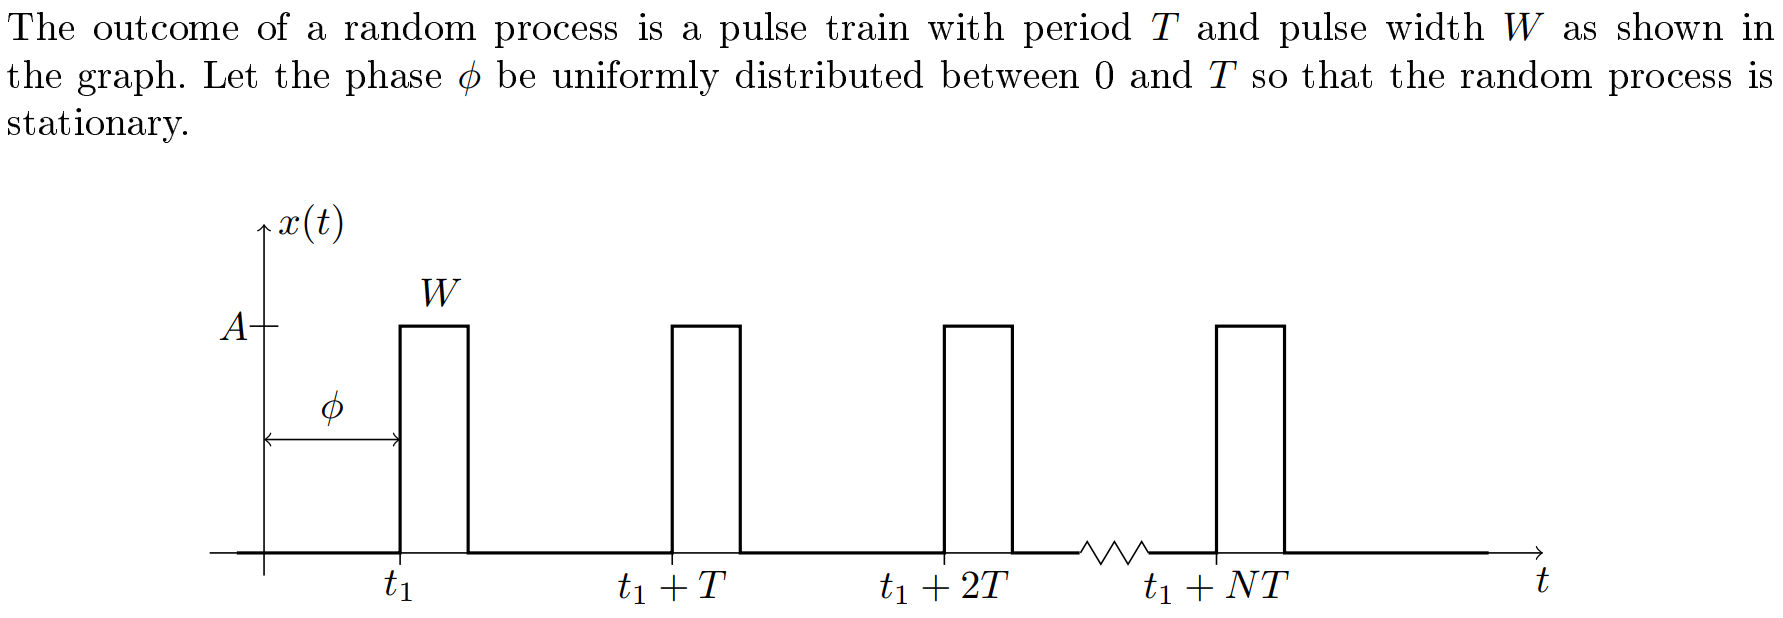

### 1) Sketch and explain what the autocorrelation looks like

### [✔] 2) Use computer simulations to verify the above result

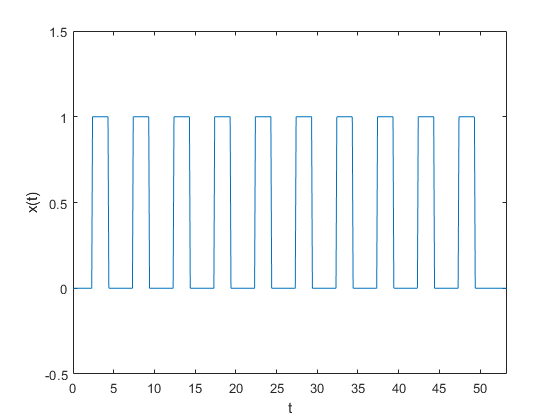

A = 1;
W = 2;  % Pulse width
T = 5; % Period width
N = 10;

% Random number from a uniform distribution in the open interval (a, b)
% a = 0; b = T; random_number = (b-a)*rand + a
phi = T*rand(1);

maxT = phi+W/2 + T*N;

t=0:.1:maxT;   % Time vector 
d= phi+W/2:T:phi+W/2+T*N-1; % Delay vector
y = pulstran(t,d,'rectpuls', W);
plot(t,y)

ylabel('x(t)');
xlabel('t');
ylim([-0.5, A+0.5]);
xlim([0, max(t)]);

Autocorrelation is symmetrical around zero.

[r_xx, lags] = xcorr(y, 'biased');
plot(lags, r_xx);
ylabel('Correlation r_x');
xlabel('Lag (k)')

## ADSI Problem 4.4: MA(q) processes

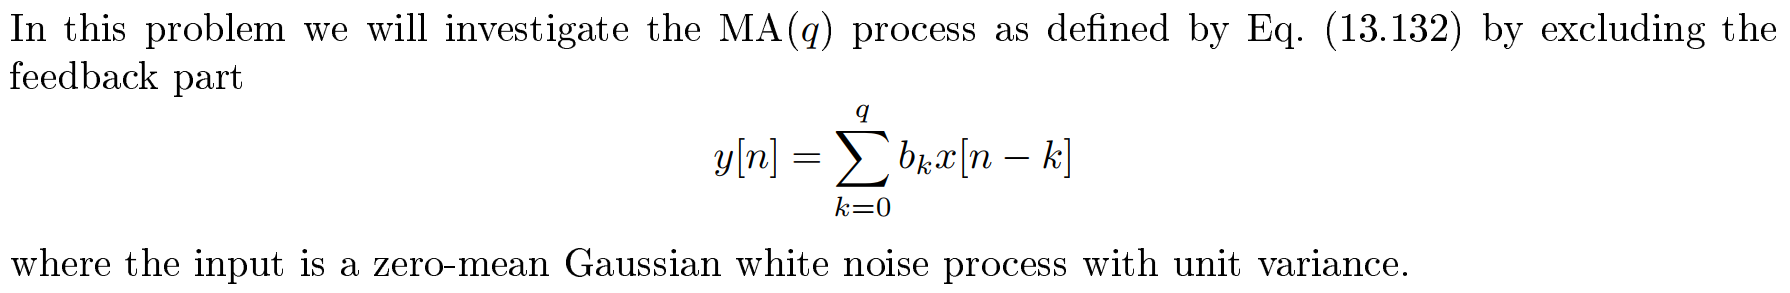

### [✔] 1) Write out the full expressions

The general $\mathrm{ARMA}\left(p,q\right)$is given by the difference equation:

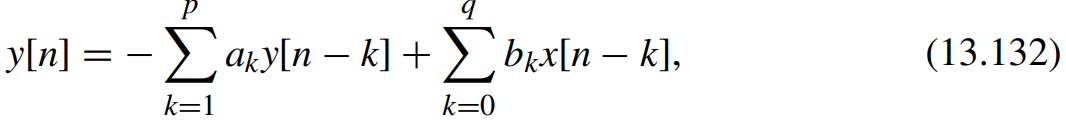

When the feedback part is excluded, all values of $a_k$ is set to zero, we are left with:


$$y\left\lbrack n\right\rbrack =\sum_{k=0}^q b_k \;x\left\lbrack n-k\right\rbrack$$


We can write out the full expressions for the difference processes as follows:


$$\mathrm{MA}\left(0\right)\;\;\to \;\;y\left\lbrack n\right\rbrack =b_0 \;x\left\lbrack n\right\rbrack$$
 


$$\mathrm{MA}\left(1\right)\;\;\to \;\;y\left\lbrack n\right\rbrack =b_0 \;x\left\lbrack n\right\rbrack +b_1 \;x\left\lbrack n-1\right\rbrack$$



$$\mathrm{MA}\left(2\right)\;\;\to \;\;y\left\lbrack n\right\rbrack =b_0 \;x\left\lbrack n\right\rbrack +b_1 \;x\left\lbrack n-1\right\rbrack +b_2 \;x\left\lbrack n-2\right\rbrack$$



$$\mathrm{MA}\left(3\right)\;\;\to \;\;y\left\lbrack n\right\rbrack =b_0 \;x\left\lbrack n\right\rbrack +b_1 \;x\left\lbrack n-1\right\rbrack +b_2 \;x\left\lbrack n-2\right\rbrack +b_3 \;x\left\lbrack n-3\right\rbrack$$


### 2) Calcute the autocorrelation for the MA processes

The autocorrelation function of a random process is defined as:

 
$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack y\left(n\right)y\left(n-\ell \right)\right\rbrack$$


To compute the autocorrelation for the $\mathrm{MA}\left(0\right)$, just plug its difference equation into this equation:

 
$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack b_0 \;x\left(n\right)\cdot b_0 \;x\left(n-\ell \right)\right\rbrack$$


 
$$r_{\textrm{yy}} \left(\ell \right)=b_0^2 E\left\lbrack x\left(n\right)\cdot x\left(n-\ell \right)\right\rbrack$$



$$r_{\textrm{yy}} \left(\ell \right)=b_0^2 \;r_{\mathrm{xx}} \left(\ell \right)$$
 

Since $r_{\textrm{xx}} \left(\ell \right)=\sigma^2 \delta \left(\ell \right)=\delta \left(\ell \right)$. ***Why?***


$$r_{\textrm{yy}} \left(\ell \right)=b_0^2 \;\delta \left(\ell \right)$$
 

The autocorrelation for the $\textrm{MA}\left(1\right)$ process is:


$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack \left(b_0 \;x\left\lbrack n\right\rbrack +b_1 \;x\left\lbrack n-1\right\rbrack \right)\cdot \left(b_0 \;x\left\lbrack n-\ell \right\rbrack +b_1 \;x\left\lbrack n-\ell -1\right\rbrack \right)\right\rbrack$$



$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack b_0^2 \;x\left\lbrack n\right\rbrack x\left\lbrack n-\ell \right\rbrack +b_0 b_1 x\left\lbrack n\right\rbrack x\left\lbrack n-\ell -1\right\rbrack +b_0 b_1 \;x\left\lbrack n-1\right\rbrack \;x\left\lbrack n-\ell \right\rbrack +b_1^2 x\left\lbrack n-1\right\rbrack x\left\lbrack n-\ell -1\right\rbrack \right\rbrack$$



$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack b_0^2 \;x\left\lbrack n\right\rbrack x\left\lbrack n-\ell \right\rbrack +b_0 b_1 \left(x\left\lbrack n\right\rbrack x\left\lbrack n-\ell -1\right\rbrack +x\left\lbrack n-1\right\rbrack \;x\left\lbrack n-\ell \right\rbrack \right)+b_1^2 x\left\lbrack n-1\right\rbrack x\left\lbrack n-\ell -1\right\rbrack \right\rbrack$$



$$r_{\textrm{yy}} \left(\ell \right)=b_0^2 \;E\left\lbrack x\left\lbrack n\right\rbrack x\left\lbrack n-\ell \right\rbrack \right\rbrack +b_0 b_1 \;E\left\lbrack \left(x\left\lbrack n\right\rbrack x\left\lbrack n-\ell -1\right\rbrack +x\left\lbrack n-1\right\rbrack \;x\left\lbrack n-\ell \right\rbrack \right)\right\rbrack +b_1^2 \;E\left\lbrack x\left\lbrack n-1\right\rbrack x\left\lbrack n-\ell -1\right\rbrack \right\rbrack$$



$$r_{\textrm{yy}} \left(\ell \right)=b_0^2 \;E\left\lbrack x\left\lbrack n\right\rbrack x\left\lbrack n-\ell \right\rbrack \right\rbrack +b_0 b_1 \;\left(E\left\lbrack x\left\lbrack n\right\rbrack x\left\lbrack n-\ell -1\right\rbrack \right\rbrack +E\left\lbrack x\left\lbrack n-1\right\rbrack \;x\left\lbrack n-\ell \right\rbrack \right\rbrack \right)+b_1^2 \;E\left\lbrack x\left\lbrack n-1\right\rbrack x\left\lbrack n-\ell -1\right\rbrack \right\rbrack$$


Since

- 
$$E\left\lbrack x\left\lbrack n\right\rbrack x\left\lbrack n-\ell \right\rbrack \right\rbrack =r_{\mathrm{xx}} \left(\ell \right)$$


- 
$$E\left\lbrack x\left\lbrack n\right\rbrack x\left\lbrack n-\ell -1\right\rbrack \right\rbrack =r_{\textrm{xx}} \left(\ell -1\right)$$


- 
$$E\left\lbrack x\left\lbrack n-1\right\rbrack x\left\lbrack n-\ell \right\rbrack \right\rbrack =r_{\mathrm{xx}} \left(\ell +1\right)$$


### 3) Calculate power density spectra

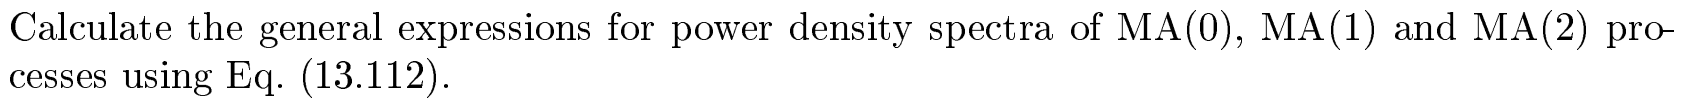

The power spectral density (PSD) is defined as:

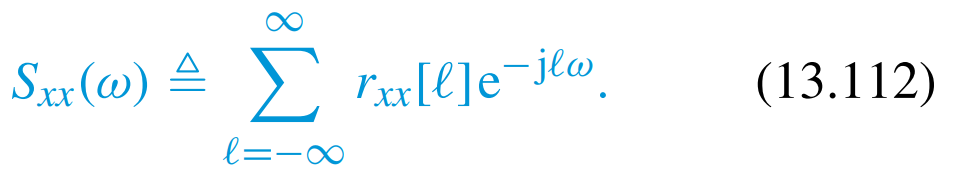

In 2) we found that the autocorrelation for $\mathrm{MA}\left(0\right)$ is $r_{\textrm{yy}} \left(\ell \right)=b_0^2 \;\delta \left(\ell \right)$, so plug it in this PSD formula:


$$S_{\textrm{yy}}^{\mathrm{MA}\left(0\right)} \left(\omega \right)=\sum_{\ell =-\infty }^{\infty } r_{\textrm{yy}} \left(\ell \right)e^{-\j \ell \omega } =\sum_{\ell =-\infty }^{\infty } b_0^2 \;\delta \left(\ell \right)e^{-\j \ell \omega }$$


We notice that $r_{\textrm{yy}} \left(\ell \right)$ has non-zero value only when $\ell =0$. Therefore, the terms for when $\ell \not= 0$ are zero. We can, therefore, remove the infinite sum. Since $\delta \left(0\right)=1$and $e^{-\j 0\omega } =1$, we have:


$$S_{\textrm{yy}}^{\mathrm{MA}\left(0\right)} \left(\omega \right)=b_0^2 \;\delta \left(0\right)e^{-\j 0\omega } =b_0^2 \cdot 1\cdot 1=b_0^2$$


### [✔] 4) Plot the power density spectra given coefficients

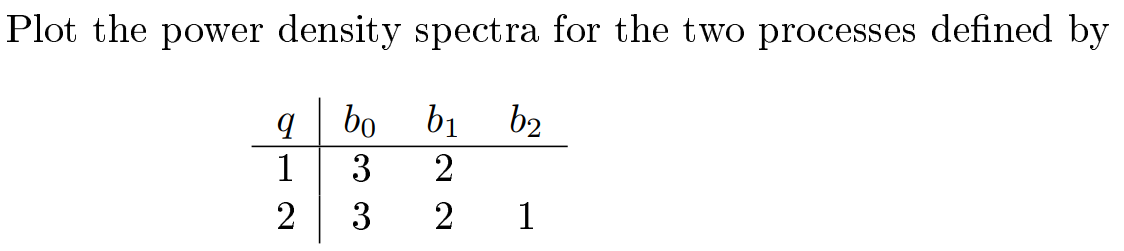

We are given the coefficients for $S_{\textrm{yy}}^{\textrm{MA}\left(1\right)} \left(\omega \right)$and $S_{\textrm{yy}}^{\textrm{MA}\left(2\right)} \left(\omega \right)$. We use results from 3) to plot the power density spectra for the two processes.

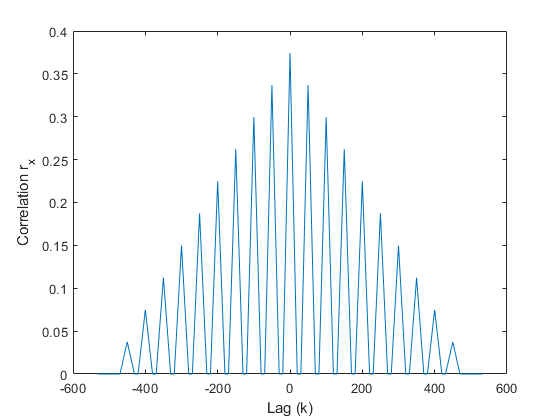

b0=3; b1=2; b2=1;
w=0:0.001:2*pi;

S1=(b0^2+b1^2)+2*b0*b1*cos(w);
S2=(b0^2+b1^2+b2^2)+2*(b0*b1+b1*b2)*cos(w)+2*b0*b2*cos(2*w);
plot(w,S1,w,S2)
legend('S_{yy}^{MA(1)}(\omega)','S_{yy}^{MA(2)}(\omega)')
xlabel('Frequency (\omega)')
ylabel('Power density sectra S_{yy}(\omega)')
xlim([0,2*pi])

## ADSI Problem 4.5: MA processes and phase properties

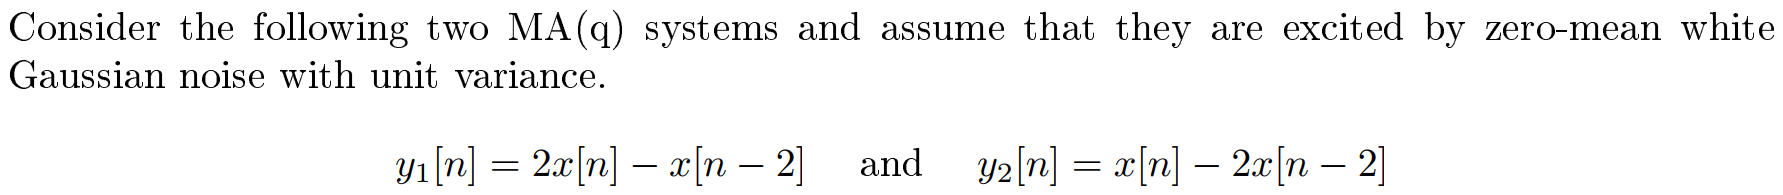

### [✔] 1) What is the order q of the processes

The order $q$ of an $\mathrm{MA}\left(q\right)$ process is given by the longest delay, i.e., $x\left\lbrack n-q\right\rbrack$. Therefore, both systems are of order 2.

### [✔] 2) Compare the phase properties of the two systems

To determine the phase properties of a system, we need to plot where its the zeros are located in relation to the unit circle in a zero-pole plot. If all zeros are located within the unit circle, then we have a minimum-phase system.

h1 = [2, 0, -1]; % Impulse response for y1[n]
zplane(h1);

From the zero-pole plot, we observe that all the zeros are within the unit circle. Therefore, we can conclude that the system $y_1 \left\lbrack n\right\rbrack$ is a minimum-phase.

Let us make the zero-plot for the system $y_2 \left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -2x\left\lbrack n-2\right\rbrack$

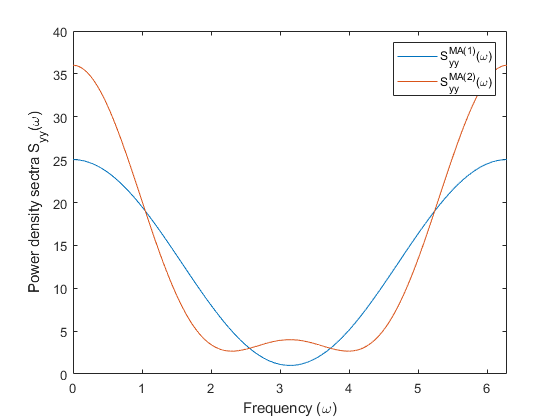

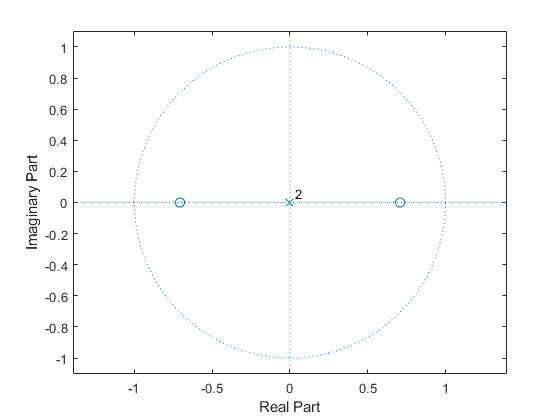

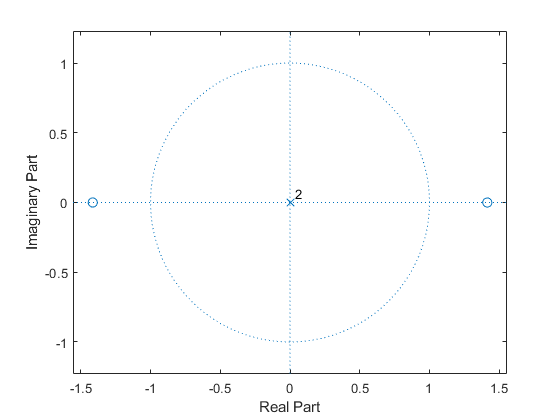

h2 = [1, 0, -2]; % Impulse response for y2[n]
zplane(h2);

Since both zeros are outside the unit circle, we can conclude the system $y_2 \left\lbrack n\right\rbrack$ is a maximum-phase system.

### 3) Calculate and plot the power density spectra of the two systems and comment on the result

## ADSI Problem 4.6: MA processes, output corrupted

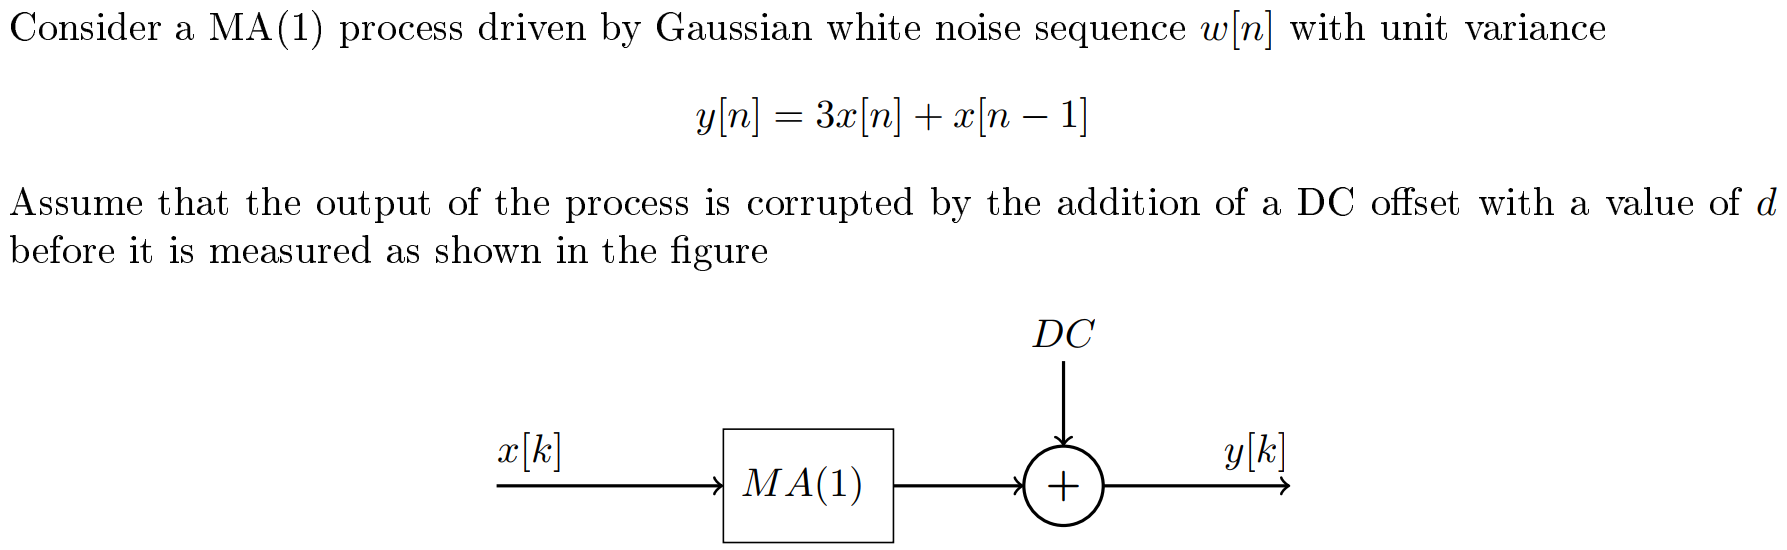

### 1) Calculate the autocorrelation of the corrupted signal

### 2) How is the power density spectrum of the *MA*(1) process affected by the DC-offset? 

## Exam 2012 Problem 4: Wiener filter for recovering corrupted signal

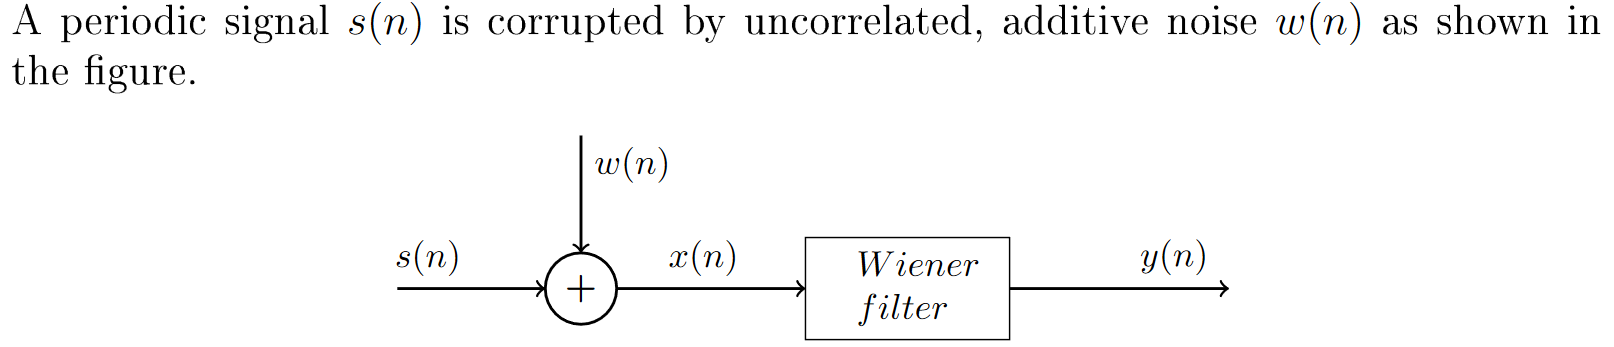

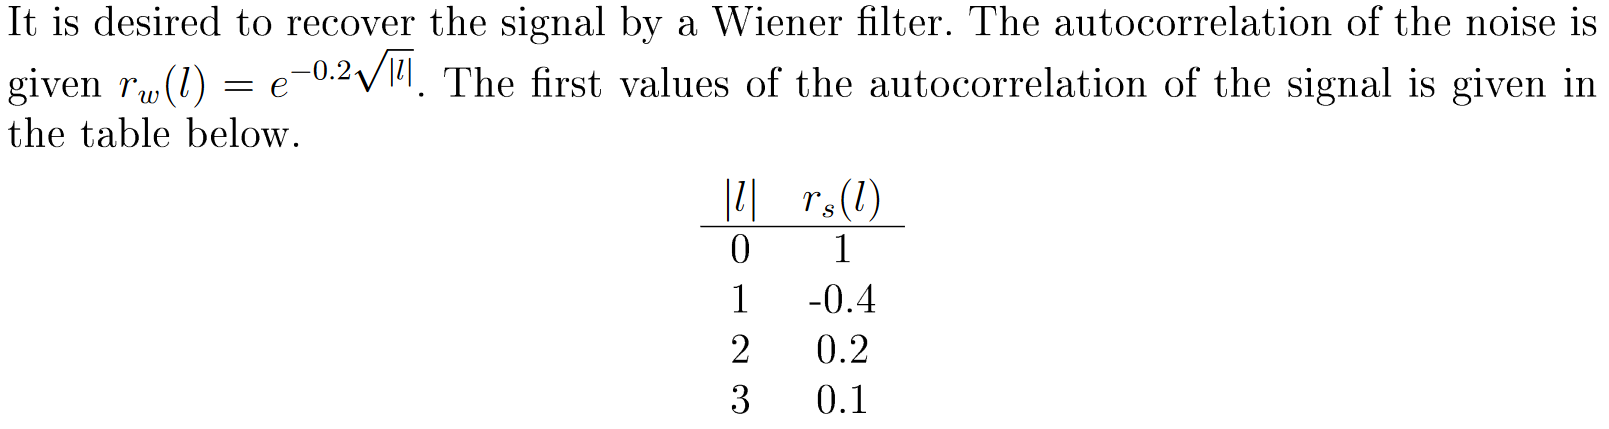

### 1) Design a 3 tap Wiener filter to recover s(n)

### 2) Calculate the minimum mean square error

### 3) Discuss another Wiener filter with 2x noise amplitude